# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

Original: January, 2021 D.Cardinal, ported to iset3d-v4, January, 2022, D.Cardinal

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
sceneLuminance = 200;
numRays = 512;
filmResolution = 512;

sceneChoice = "CornellBoxReference";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

% 'apertureDiameter', apertureDiameter
pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','wide.40deg.6.0mm.json'); 

Read 7 materials.
Read 0 textures.
***Scene parsed.


piWrite(pbrtCPScene.thisR);

pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, ...
    'sceneLuminance', sceneLuminance);

Read 7 materials.
Read 0 textures.
***Scene parsed.



% we have trouble if we try to work on the same recipe
tR = pinholeCPScene.thisR; % just less characters
% make output file in new folder
[oP, oF, oE] = fileparts(tR.get('output file'));

tR.set('output file', fullfile([oP '_pinhole'], [oF oE]));
%tR.set('scene name', [oF '_pinhole']);

piWrite(tR);
%pinholeCPScene.thisR.set('focaldistance', '.005');

if strcmp(sceneChoice, "CornellBoxReference")
    %bunny = load('bunny.mat');
    bunny = piAssetLoad('bunny.mat');
    bunny.name = 'Bunny';
    if isfield(bunny,'thisR')
        pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, bunny.thisR);
        pinholeCPScene.thisR = piRecipeMerge(pinholeCPScene.thisR, bunny.thisR);
    else
        piAssetAdd(pbrtCPScene.thisR, '0001ID_root', bunny);
        piAssetAdd(pinholeCPScene,bunny.assetTree.Node{1});
        pbrtCPScene.thisR.set('material', 'add', bunny.matList{1});
        pinholeCPScene.thisR.set('material', 'add', bunny.matList{1});
    end
    pbrtCPScene.thisR.set('asset', 'Bunny_B', 'world position',...
        [0 0 1.3]);
    pinholeCPScene.thisR.set('asset', 'Bunny_B', 'world position',...
        [0 0 1.3]);

    %if you want object motion
    %pbrtCPScene.objectMotion = {{bunny_id, [0 .1 0], [0 0 0]}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', 'Bunny_B', 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;

%{
% Load other objects, but needs updating for v4
    mcc = load('mccCB.mat');
    [~, mcc_id] = pbrtCPScene.thisR.set('asset',1, 'add', mcc.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', mcc.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    [~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR.set('asset',1, 'add', coord.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', coord.matList{1});
%}
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
baseRez = filmResolution;
aspectRatio = 4/3;
ourSensor = sensorCreate('imx363'); 
ourSensor = sensorSet(ourSensor, 'size', [baseRez, baseRez * aspectRatio]);
pinholeSensor = sensorCreate('imx363'); 
pinholeSensor = sensorSet(pinholeSensor, 'size', [baseRez, baseRez * aspectRatio]);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', ourSensor); 

% try to make the pinhole a pinhole:)
% if it works, should integrate into cpCamera
pinholeCamera = cpBurstCamera();
pinholeCamera.cmodules(1) = cpCModule('sensor', pinholeSensor);
% with a small sensor, too large an f/# causes diffraction, so we pick a
% middle ground
pinholeCamera.cmodules(1).oi.optics = opticsSet(pinholeCamera.cmodules(1).oi.optics,'fnumber',8);

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

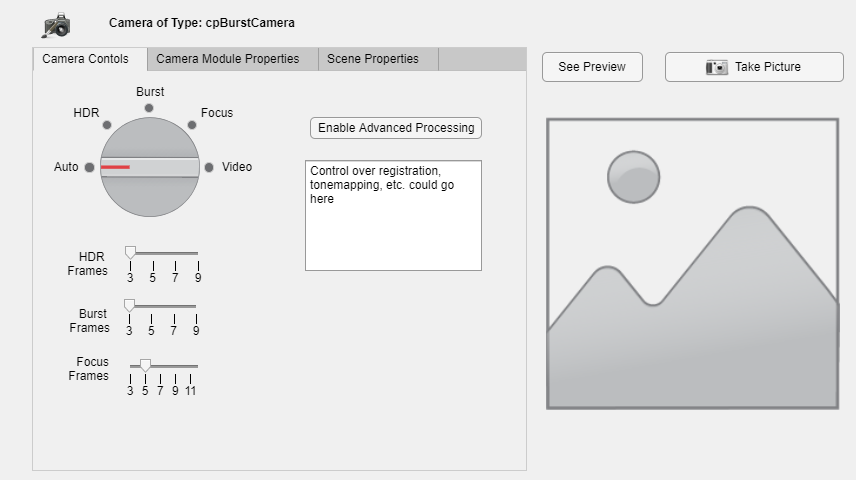

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

singleImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Single Auto Image',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

Elapsed time is 0.927303 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.84
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:   5.79
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.73
Complete render took: 8.33e+00 seconds.*** Rendering time for cornell_box:  8.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.84
Render: docker --context

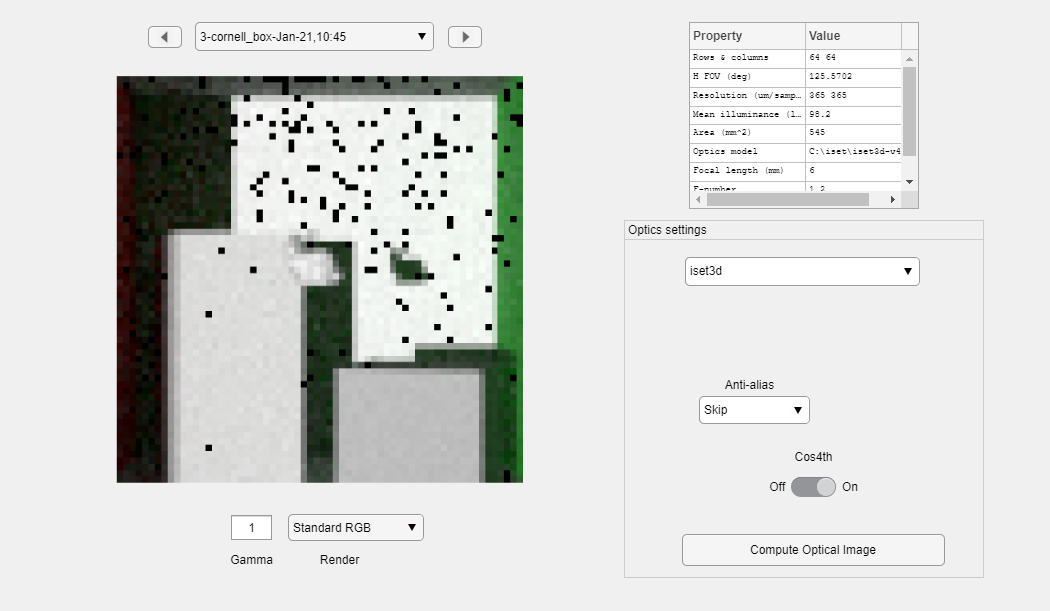

Elapsed time is 0.844020 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.84
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:   5.56
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.74
Complete render took: 8.12e+00 seconds.*** Rendering time for cornell_box:  8.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.83
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:  10.22
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.74
Complete render took: 1.29e+01 seconds.*** Rendering time for cornell_box:  12.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 0.947985 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.84
Render: docker --contex


burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

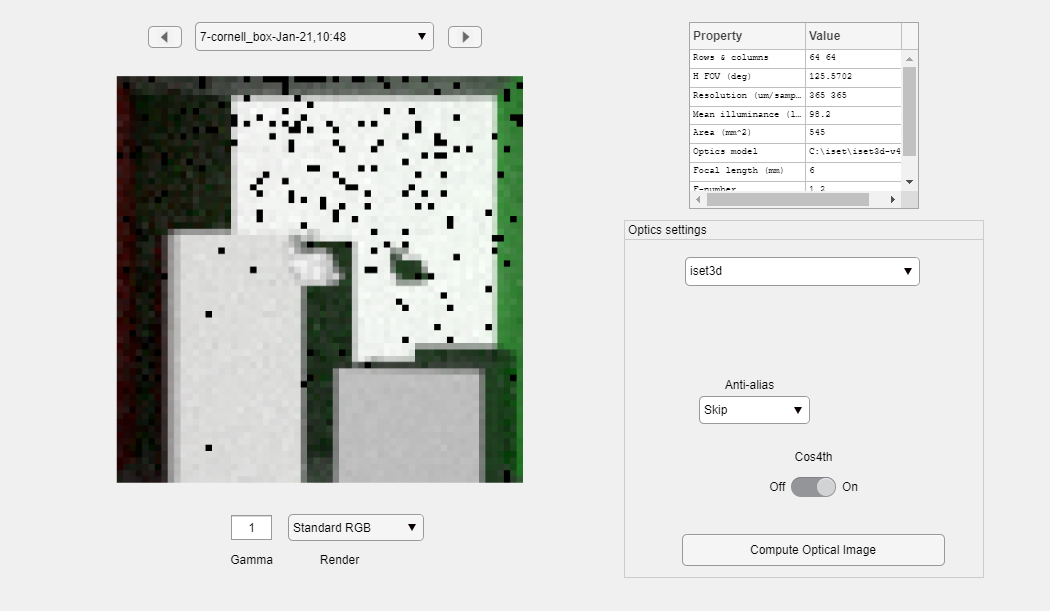

Elapsed time is 0.849980 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.84
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:   5.60
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.85
Complete render took: 8.25e+00 seconds.*** Rendering time for cornell_box:  8.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.86
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:  10.00
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.85
Complete render took: 1.27e+01 seconds.*** Rendering time for cornell_box:  12.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 1.042753 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.97
Render: docker --contex


stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 9, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

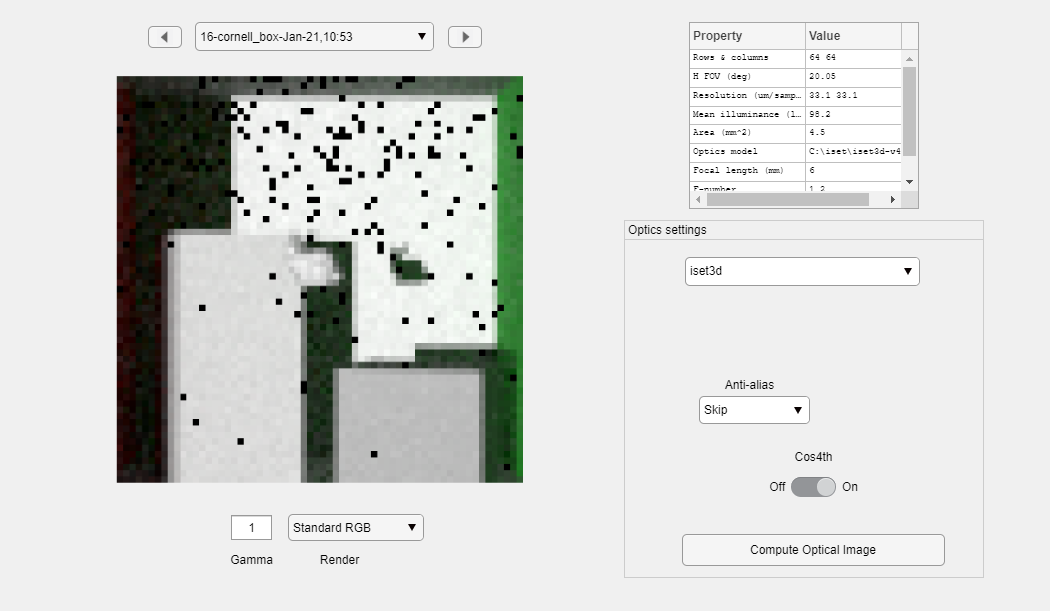

Elapsed time is 0.968990 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box_pinhole/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box_pinhole/
Pushed scene to remote in:   0.86
Render: docker --context render-vista exec -i  pbrt-gpu-Windows2652 sh -c "cd /iset/iset3d-v4/local/cornell_box_pinhole && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:   9.86
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box_pinhole/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box_pinhole/renderings
Retrieved output in:   0.75
Complete render took: 1.25e+01 seconds.*** Rendering time for cornell_box:  12.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box_pinhole/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box_pinhole/
P

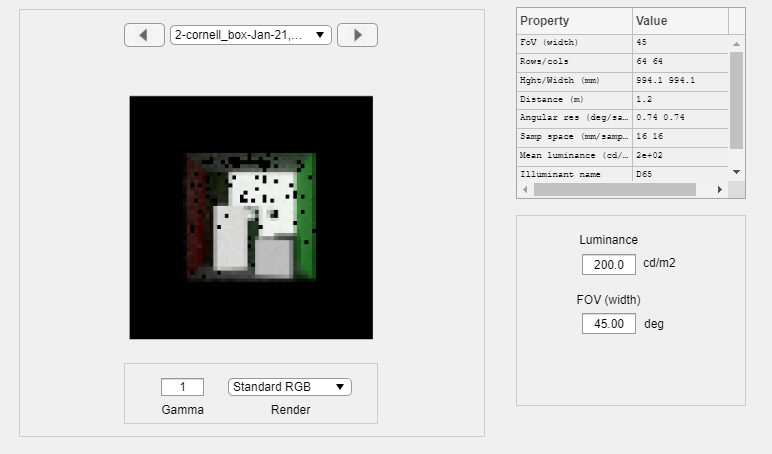



pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

Burst vs. Stacked with no motion

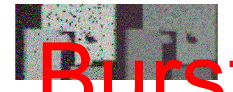

%{
thisR = pinholeCPScene.thisR;

%}

cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');

Pinhole vs. Stacked with no motion

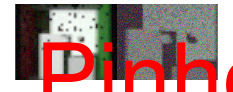

cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');

Pinhole vs. Burst with no motion

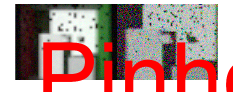


cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation Quadro T2000/PCIe/SSE2with driver version: 4.6.0 NVIDIA 472.39


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 267.625 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 881.4998 total seconds.
